# Compare the male/female FA along 20 tracts

We executed the AFQ Docker container on the Simons VIP data. This produced a set of fractional anisotropy files on multiple tracts. Here, we analyze the data for sex differences.

- Search for the AFQ fractional anisotropy files in male and female subjects

- Download the files and build a m atrix of position x tract x subject

- Plot and compare the male and female tract curves

RF/BW PoST Team 2016

## Open up the scitran client

% Where the data live
st = scitran('vistalab');

% Change to a convenient place to store local data
chdir(fullfile(vistaRootPath,'local'));

## Initialize tract names

% tractNames = ...
%     {'Left Thalamic Radiation','Right Thalamic Radiation','Left Corticospinal',...
%     'Right Corticospinal','Left Cingulum Cingulate','Right Cingulum Cingulate',...
%     'Left Cingulum Hippocampus','Right Cingulum Hippocampus','Callosum Forceps Major',...
%     'Callosum Forceps Minor','Left IFOF','Right IFOF','Left ILF','Right ILF',...
%     'Left SLF','Right SLF','Left Uncinate','Right Uncinate','Left Arcuate','Right Arcuate'};

tractNames = ...
    {'Left ThalRad','Right ThalRad','Left CST',...
    'Right CST','Left CC','Right CC',...
    'Left Cing Hipp','Right Cing Hipp','Forceps Major',...
    'Forceps Minor','Left IFOF','Right IFOF','Left ILF','Right ILF',...
    'Left SLF','Right SLF','Left Unc','Right Unc','Left Arc','Right Arc'};

nTracts = length(tractNames);

## Find the fa.csv files for the male subjects

% These are files in an analysis 
% They are in the project SVIP Released data.  
% They have 'fa.csv' in their name.  
% First, we find the males.
maleFiles = st.search('files in analysis',...
    'project label contains','SVIP Released Data',...
    'file name contains','fa.csv',...
    'subject sex','male');
nMales = length(maleFiles);
fprintf('Found %d male fa.csv analysis files\n',nMales);

Found 89 male fa.csv analysis files


## Now the females

femaleFiles = st.search('files in analysis',...
    'project label contains','SVIP Released Data',...
    'file name contains','fa.csv',...
    'subject sex','female');
nFemales = length(femaleFiles);
fprintf('Found %d female fa.csv analysis files\n',nFemales);

Found 56 female fa.csv analysis files


## Read the FA tract profiles

% We place them into a single 3D matrix: position x tract x subject
nPositions = 100;
maleTracts = zeros(nPositions,nTracts,nMales);
str = sprintf('Downloading %d tracts',nTracts*nMales);
wbar = waitbar(0,str);
for ii=1:nMales
    wbar = waitbar(ii/nMales,wbar,str);
    st.get(maleFiles{ii},'destination','male.csv');
    d = csvread('male.csv',1,0);
    maleTracts(:,:,ii) = d;
end
delete(wbar);

## Females

femaleTracts = zeros(nPositions,nTracts,nFemales);
str = sprintf('Downloading %d tracts',nTracts*nFemales);
wbar = waitbar(0,str);
for ii=1:nFemales
    wbar = waitbar(ii/nFemales,wbar,str);
    st.get(femaleFiles{ii},'destination','female.csv');
    d = csvread('female.csv',1,0);
    femaleTracts(:,:,ii) = d;
end
delete(wbar);

## We don't really need to save

% But in case we want to do a different analysis, I wrote them out
save('maleTracts.mat','maleTracts');
save('femaleTracts.mat','femaleTracts');

## Plot the male and female tract profiles

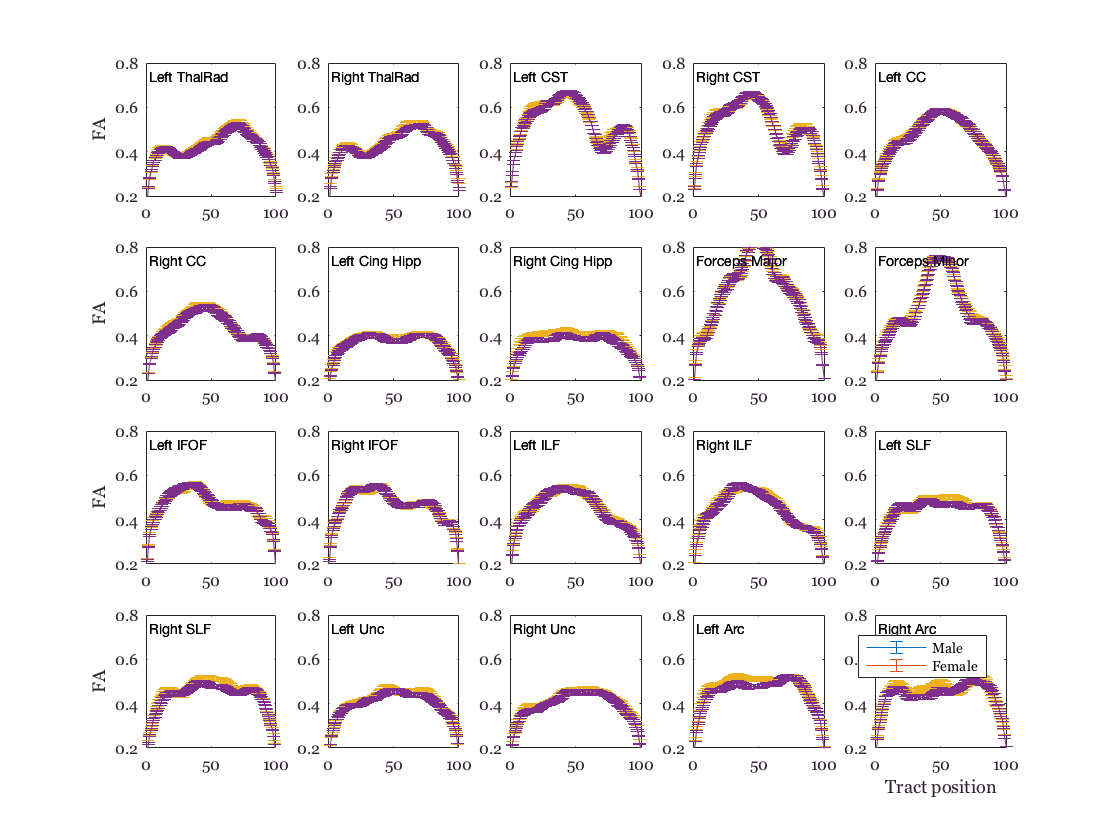

% stNewGraphWin('format','upper left big');
figure;
for tt=1:nTracts
    subplot(4,5,tt)
    X = (1:100)'; Y = nanmean(maleTracts,3);
    flag = 0; E = nanstd(maleTracts,flag,3);
    errorbar(X,Y(:,tt)',E(:,tt)'/sqrt(nMales));
    
    Y = nanmean(femaleTracts,3);
    flag = 0; E = nanstd(femaleTracts,flag,3);
    hold on
    errorbar(X,Y(:,tt)',E(:,tt)'/sqrt(nFemales));
    set(gca,'xlim',[0 100],'ylim',[0.2 0.8],'fontsize',8);
    
    text(2,0.7,sprintf('%s\n',tractNames{tt}),'fontsize',7);
    
    if ~mod(tt-1,5), ylabel('FA'); end
end
xlabel('Tract position')

legend({'Male','Female'})